# Compressed Sensing Tutorial

## Prepare workspace

clear all; close all; clc;

## Import image

cameraman = imread('cameraman.tif');
lena = imread('lena_std.tif');
lena2 = rgb2gray(lena);
whos cameraman

  Name             Size             Bytes  Class    Attributes

  cameraman      256x256            65536  uint8              



whos lena

  Name        Size                Bytes  Class    Attributes

  lena      512x512x3            786432  uint8              



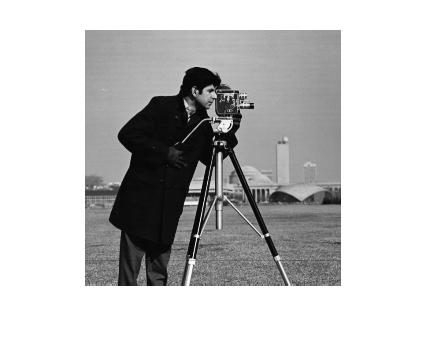

imshow(cameraman);    % exmaple of binary image

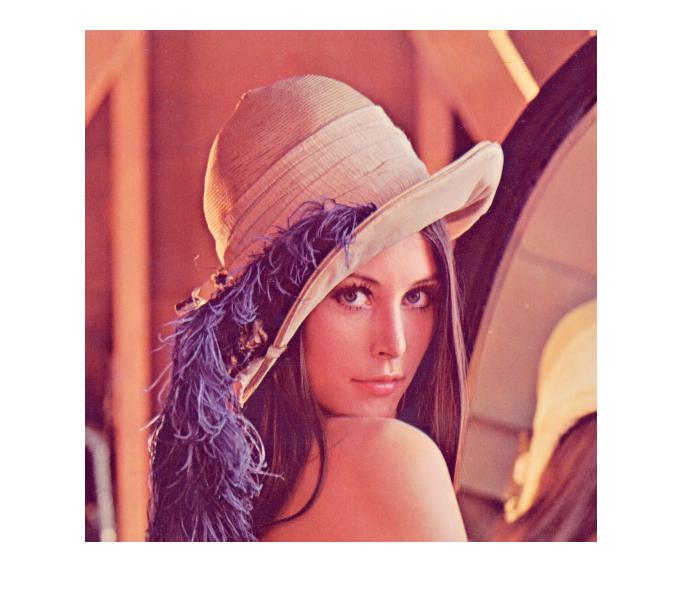

figure; imshow(lena); % example of rgb image

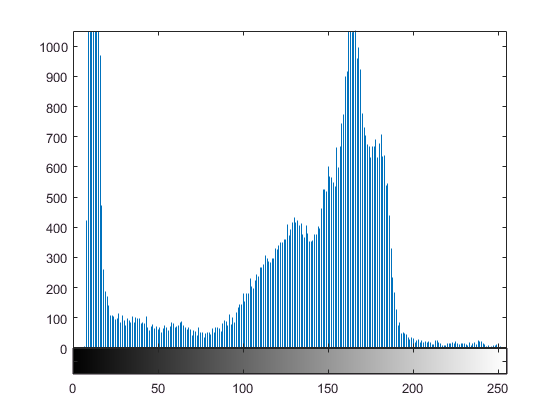

figure; imhist(cameraman)

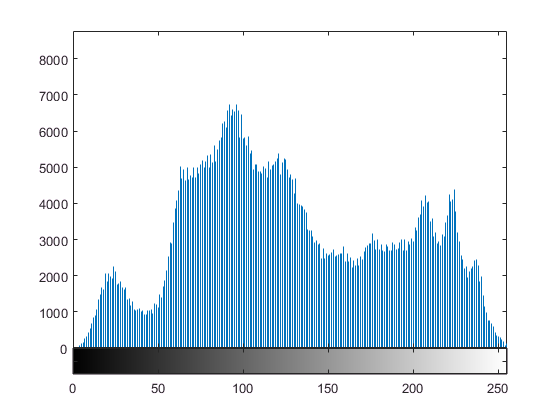

figure; imhist(lena)

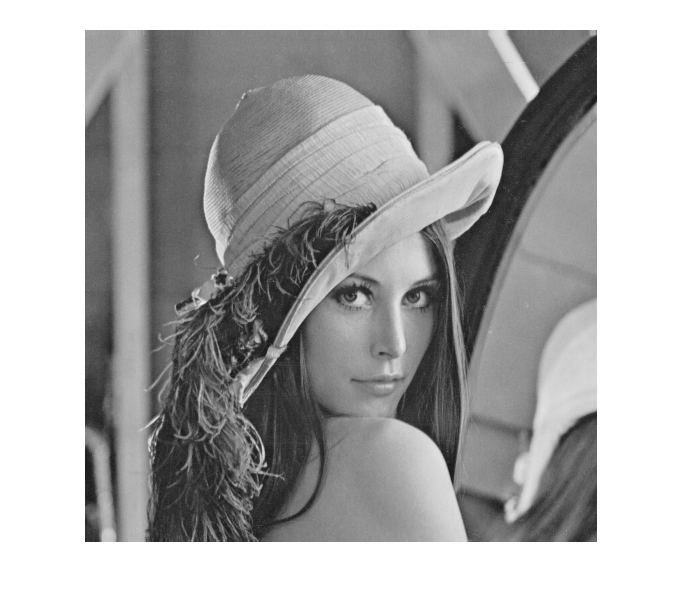

figure; imshow(lena2);

## Fourier Transform

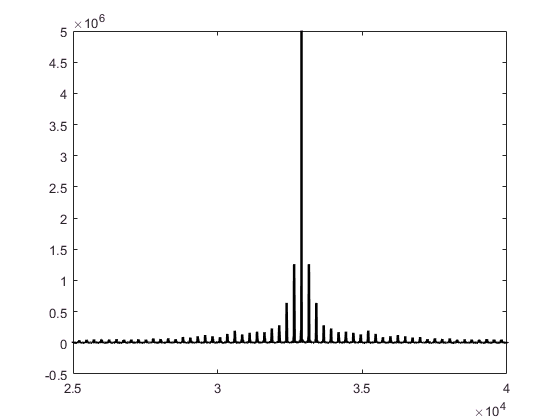

lena_4_fft = double(lena2);
[nx1, ny1] = size(cameraman);
[nx2, ny2] = size(lena_4_fft);
fft_cameraman = fftshift(fft2(cameraman));
fft_lena = fftshift(fft2(lena_4_fft));
figure; plot(reshape(abs(fft_cameraman), nx1*ny1, 1), 'k', 'Linewidth', [2])
set(gca,'Xlim', [2.5*10^4 4*10^4], 'Ylim', [-0.5*10^6 5*10^6])

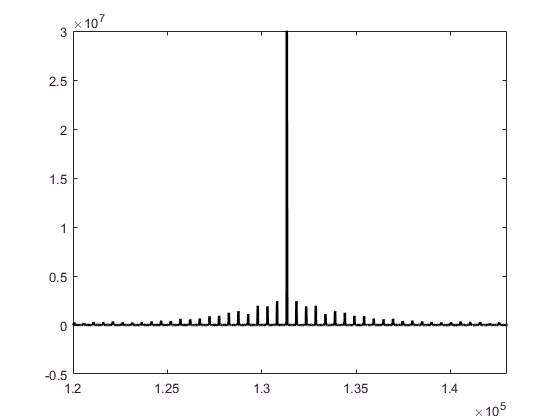

figure; plot(reshape(abs(fft_lena), nx2*ny2, 1), 'k', 'Linewidth', [2])
set(gca,'Xlim', [1.2*10^5 1.43*10^5], 'Ylim', [-0.5*10^7 3*10^7])

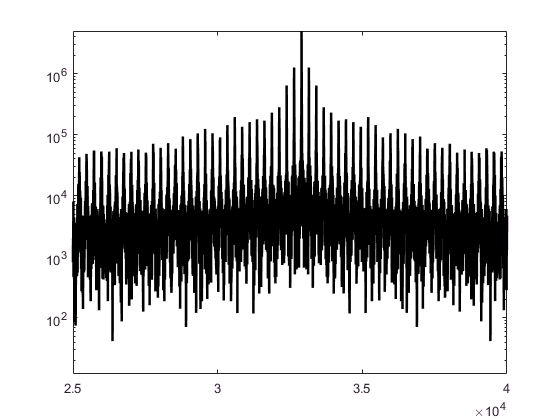

figure; semilogy(reshape(abs(fft_cameraman), nx1*ny1, 1), 'k', 'Linewidth', [2])
set(gca,'Xlim', [2.5*10^4 4*10^4], 'Ylim', [-0.5*10^6 5*10^6])

figure; semilogy(reshape(abs(fft_lena), nx2*ny2, 1), 'k', 'Linewidth', [2])

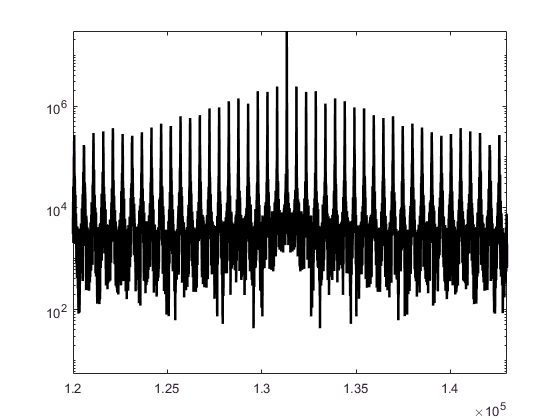

set(gca,'Xlim', [1.2*10^5 1.43*10^5], 'Ylim', [-0.5*10^7 3*10^7])

## Power Spectrum

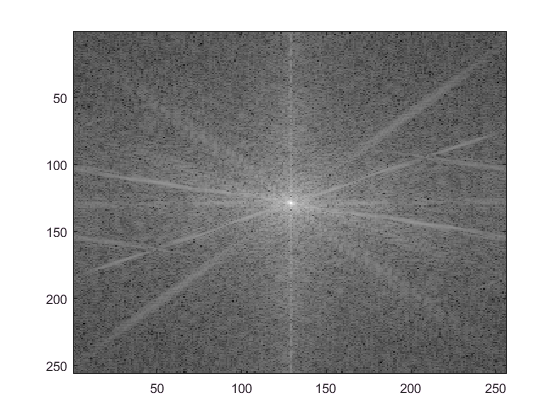

figure; colormap gray; imagesc(log10(abs(fft_cameraman)));

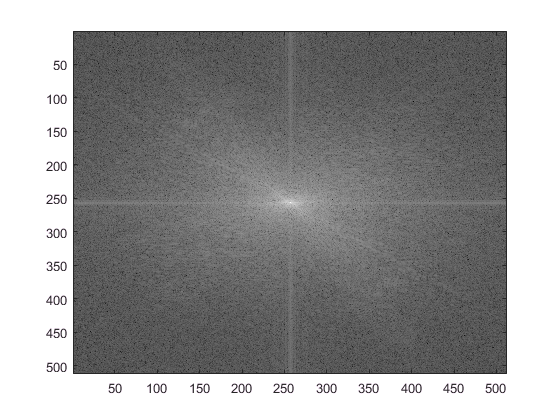

figure; colormap gray; imagesc(log10(abs(fft_lena))); % power spectrum

## Truncation

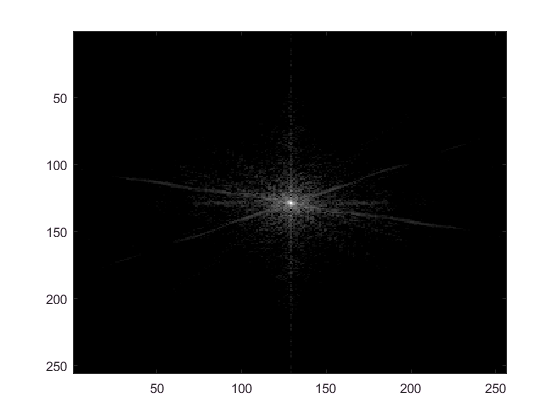

fft_cameraman(find(abs(fft_cameraman)<=max(quantile(abs(fft_cameraman(:)),10))))=0;
fft_lena(find(abs(fft_lena)<=max(quantile(abs(fft_lena(:)),10))))=0;
figure; colormap gray; imagesc(log10(abs(fft_cameraman)));

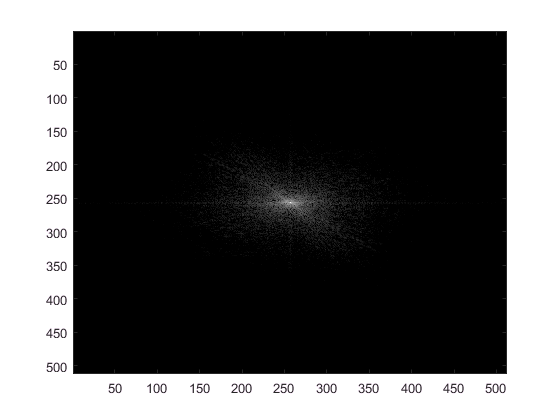

figure; colormap gray; imagesc(log10(abs(fft_lena))); % power spectrum

## Reconstruction

for cameraman image

percent = 21.9742

percent = 2.9434

percent = 0.6546

percent = 0.0198

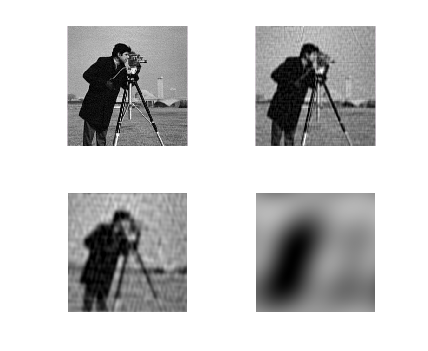

% cameraman
count_pic = 1;

for thresh = [0.005 * 10^6 0.02*10^6 0.05*10^6 0.5*10^6]
    fft2 = reshape(fft_cameraman, nx1*ny1, 1);
    count = 0;
    for j = 1:length(fft2);
        if abs(fft2(j)) < thresh
            fft2(j) = 0;
            count = count+1;
        end
    end
    percent = 100-count/length(fft2) * 100
    
    fft_low = fftshift(reshape(fft2, nx1, ny1));
    im_low = uint8(ifft2(fft_low));
    figure(1), subplot(2,2,count_pic), imshow(im_low);
    count_pic = count_pic+1;
end

for lena image

percent = 19.9699

percent = 3.7319

percent = 0.9975

percent = 0.0378

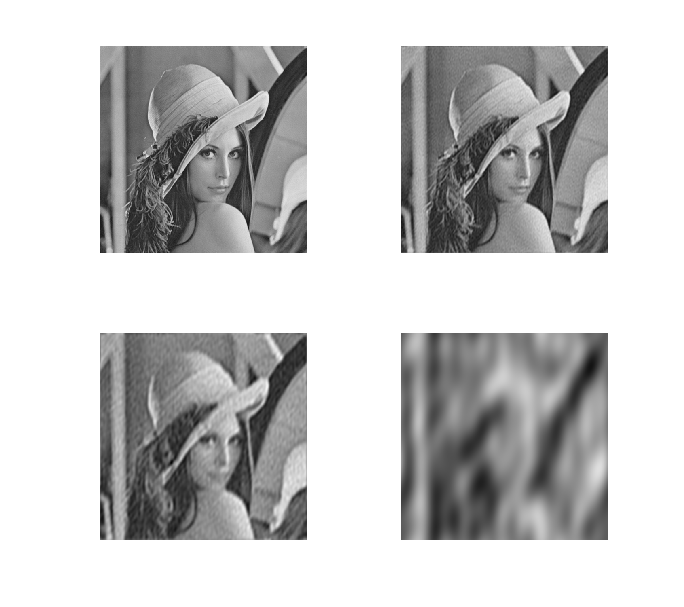

% lena
count_pic = 1;
for thresh = [0.0005 * 10^7 0.002*10^7 0.005*10^7 0.05*10^7];
    fft2 = reshape(fft_lena, nx2*ny2, 1);
    count = 0;
    for j = 1:length(fft2);
        if abs(fft2(j)) < thresh
            fft2(j) = 0;
            count = count+1;
        end
    end
    percent = 100-count/length(fft2) * 100
    
    fft_low = fftshift(reshape(fft2, nx2, ny2));
    im_low = uint8(ifft2(fft_low));
    figure(2), subplot(2,2,count_pic), imshow(im_low);
    count_pic = count_pic+1;
end

## Compressed Sensing

Image compression algorithm does; (1) first the image is taken (2) a wavelet/Fourier transform is applied in order to apply a threshold rule, and (3) the majority of information is promptly discarded. Could we instead randomly sample, let's say 5% of the pixels and still reconstruct the image? Knowing that the image is sparse allows us to do just that. In this sections, I'm going to introduce compressed sensing. To run the code below, you need to install cvx toolbox from ([http://cvxr.com/cvx/](http://cvxr.com/cvx/)). It may take 8 or 9 hours or more in usual personal computer. 

For cameraman image

 
Calling SDPT3 4.0: 15000 variables, 2500 equality constraints
------------------------------------------------------------

 num. of constraints = 2500
 dim. of socp   var  = 15000,   num. of socp blk  = 7500
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|8.6e+01|1.2e+08| 1.347038e+06  0.000000e+00| 0:1:45| chol  2  2 
 1|1.000|0.597|6.1e-08|3.5e+01|7.8e+07| 2.179745e+06  4.398288e+05| 0:3:19| chol  1  1 
 2|1.000|0.987|1.6e-08|7.0e-01|3.4e+06| 2.035527e+06  5.703216e+04| 0:6:41| chol  1  1 
 3|0.920|0.736|7.6e-09|2.7e-01|6.5e+05| 5.675139e+05  7.054532e+04| 0:9:28| 

 
Calling SDPT3 4.0: 15000 variables, 3000 equality constraints
------------------------------------------------------------

 num. of constraints = 3000
 dim. of socp   var  = 15000,   num. of socp blk  = 7500
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|8.6e+01|1.2e+08| 1.347038e+06  0.000000e+00| 0:1:54| chol  2  2 
 1|1.000|0.556|6.6e-08|3.8e+01|8.8e+07| 2.235443e+06  4.917645e+05| 0:3:49| chol  1  1 
 2|1.000|0.984|1.4e-08|8.5e-01|3.8e+06| 2.100655e+06  5.991736e+04| 0:7:29| chol  1  1 
 3|0.964|0.774|6.4e-09|2.9e-01|7.0e+05| 5.998178e+05  7.226841e+04| 0:11:13|

 
Calling SDPT3 4.0: 15000 variables, 4000 equality constraints
------------------------------------------------------------

 num. of constraints = 4000
 dim. of socp   var  = 15000,   num. of socp blk  = 7500
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|8.6e+01|1.2e+08| 1.347038e+06  0.000000e+00| 0:4:16| chol  2  2 
 1|1.000|0.489|7.5e-08|4.4e+01|1.1e+08| 2.344187e+06  5.790316e+05| 0:8:36| chol  1  1 
 2|1.000|0.992|1.2e-08|6.0e-01|3.5e+06| 2.220577e+06  5.879228e+04| 0:17:16| chol  1  1 
 3|0.874|0.780|8.4e-09|2.3e-01|5.7e+05| 5.315413e+05  8.029043e+04| 0:25:59

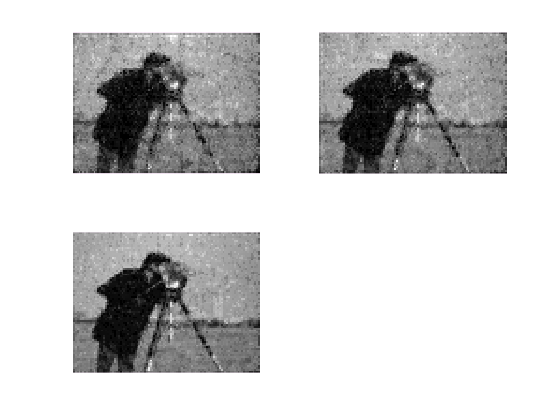

% resize image due to the computation time
resized_cameraman = imresize(cameraman, [75 100]);
cameraman2_4_fft = double(resized_cameraman);
[ny,nx] = size(cameraman2_4_fft);

% For cameraman
count_pic = 1;
for k = [2500 3000 4000 6000]; % number of sparse samples
test2 = zeros(ny, nx);
r1 = randintrlv([1:nx*ny], 793); % random permutation with set.seed(793)
r1k = r1(1:k);
for j=1:k
    test2(r1k(j))=-1;
end

% mask for image
test = zeros(ny, nx);
for j=1:k
    test(r1k(j))=1;
    Adel= reshape(idct2(test), nx*ny, 1);
    Adelta(j, :) = Adel;
    test(r1k(j))=0;
end

% L1 minimization with cvx toolbox
b = cameraman2_4_fft(r1k).';
n = nx*ny;
cvx_begin;
    variable y(n);
    minimize(norm(y, 1));
    subject to
        Adelta*y == b;
cvx_end;

% reconstruction of image
Alow = uint8((dct2(reshape(y, ny, nx))));
figure(3), subplot(2,2,count_pic), imshow(Alow);
count_pic = count_pic+1;
end

## CS for rena

 
Calling SDPT3 4.0: 15000 variables, 2500 equality constraints
------------------------------------------------------------

 num. of constraints = 2500
 dim. of socp   var  = 15000,   num. of socp blk  = 7500
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|8.6e+01|1.1e+08| 1.240972e+06  0.000000e+00| 0:1:54| chol  2  2 
 1|1.000|0.569|6.4e-08|3.7e+01|7.9e+07| 2.054209e+06  4.580951e+05| 0:4:07| chol  1  1 
 2|1.000|0.987|1.5e-08|7.3e-01|3.3e+06| 1.926917e+06  6.072306e+04| 0:7:50| chol  1  1 
 3|0.948|0.755|7.1e-09|2.7e-01|5.9e+05| 5.215885e+05  7.489711e+04| 0:11:00|

 
Calling SDPT3 4.0: 15000 variables, 3000 equality constraints
------------------------------------------------------------

 num. of constraints = 3000
 dim. of socp   var  = 15000,   num. of socp blk  = 7500
 checkdepconstr: AAt is not pos. def.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|8.6e+01|1.1e+08| 1.240972e+06  0.000000e+00| 0:1:52| chol  2  2 
 1|1.000|0.527|6.9e-08|4.1e+01|8.9e+07| 2.113097e+06  5.088847e+05| 0:3:47| chol  1  1 
 2|1.000|0.984|1.3e-08|8.8e-01|3.7e+06| 1.993443e+06  6.321754e+04| 0:7:25| chol  1  1 
 3|0.985|0.815|6.0e-09|2.6e-01|6.2e+05| 5.535876e+05  7.717995e+04| 0:11:03|

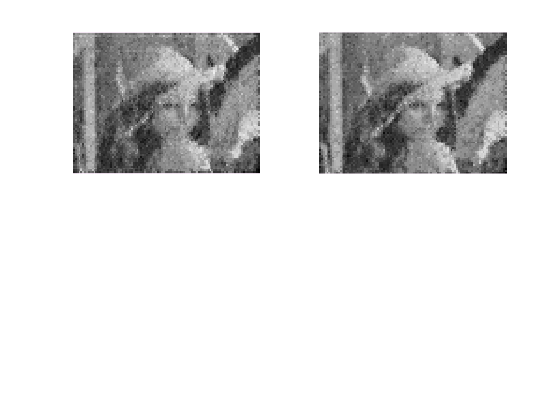

% for lena
resized_lena= imresize(lena2, [75 100]);
lena2_4_fft = double(resized_lena);
[ny,nx] = size(lena2_4_fft);

% For lena
count_pic = 1;
for k = [2500 3000 4000 6000]; % number of sparse samples
test2 = zeros(ny, nx);
r1 = randintrlv([1:nx*ny], 793); % random permutation with set.seed(793)
r1k = r1(1:k);
for j=1:k
    test2(r1k(j))=-1;
end

% mask for image
test = zeros(ny, nx);
for j=1:k
    test(r1k(j))=1;
    Adel= reshape(idct2(test), nx*ny, 1);
    Adelta(j, :) = Adel;
    test(r1k(j))=0;
end

% L1 minimization with cvx toolbox
b2 = lena2_4_fft(r1k).';
n = nx*ny;
cvx_begin;
    variable y(n);
    minimize(norm(y, 1));
    subject to
        Adelta*y == b2;
cvx_end;

% reconstruction of image
Alow = uint8((dct2(reshape(y, ny, nx))));
figure(3), subplot(2,2,count_pic), imshow(Alow);
count_pic = count_pic+1;
end

## Beating Sannon-Nyquist

addpath ./Reference/DMD-Brunton/CODE/CH09_SPARSITY/utils/
% Generate signal
Fs = 2000; p=128;
t = 0:1/Fs:1-1/Fs;
x = sin(73*2*pi*t) + sin(531*2*pi*t);
N = length(x)

N = 2000

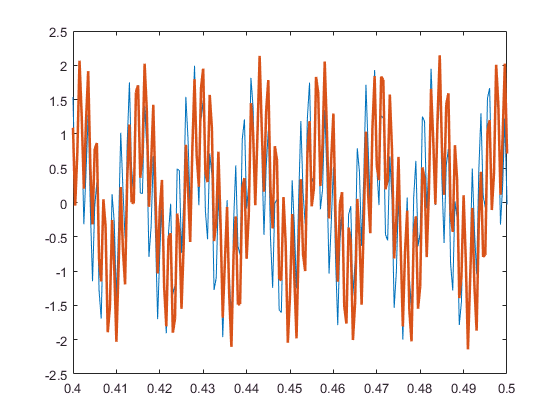


% Randomly sample signal
perm = round(rand(p, 1) * N);
y = x(perm)';

% Form matrix operators
Psi = dct(eye(N, N));
CPsi = Psi(perm, :);

% L1 minimization (through linear program)
s = cosamp(CPsi,y,10,1.e-10,10);
xreconstruct = idct(s);

% plot (Original vs Reconstruction)
figure; plot(t,x)
hold on
plot(t,xreconstruct,'LineWidth',2)
xlim([.4 .5])

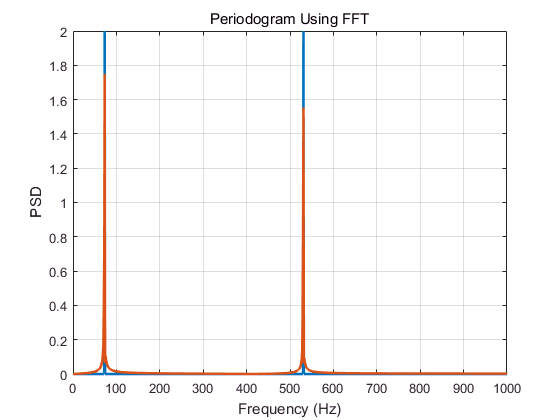



% power spectrum (Original vs Reconstruction)
rng default
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(1000)) * abs(xdft);
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/length(x):Fs/2;
figure; plot(freq,psdx,'LineWidth',2)
grid on
hold on 
xdft2 = fft(xreconstruct);
xdft2 = xdft2(1:N/2+1);
psdx2 = (1/(1000)) * abs(xdft2);
psdx2(2:end-1) = 2*psdx2(2:end-1);
plot(freq,psdx2,'LineWidth',2)
xlabel('Frequency (Hz)')
ylabel('PSD')